# Punto II: Filtrado de una señal ECG

***Por: Dayana González, David Alsina***

Cargue la señal ecg.mat que se proporciona junto a este live script. La señal esta contaminada de ruido y ustedes deben desarrolalr un conjunto de filtros para eliminar la mayor cantidad de ruido posible, mejorando la calidad de la señal. Para esto deben buscar en internet cual es el ancho de banda de la señal ECG (rango de variación de la información), así mismo como explorar en el espectro de la señal, cuales componentes pueden deberse a ruido. Con base en este análisis deben construir un filtro, o una serie de filtros, que permitan mejorar la calidad de la señal.

La señal esta muestreada con una Frecuencia de Muestreo de 500Hz. Realice una grafica de la señal original y la señal fiktrada, asi mismo como de la respuesta en frecuencia de lso filtros en amplitud y fase. Discuta sobre los filtros y los resultados de la señal filtrada.

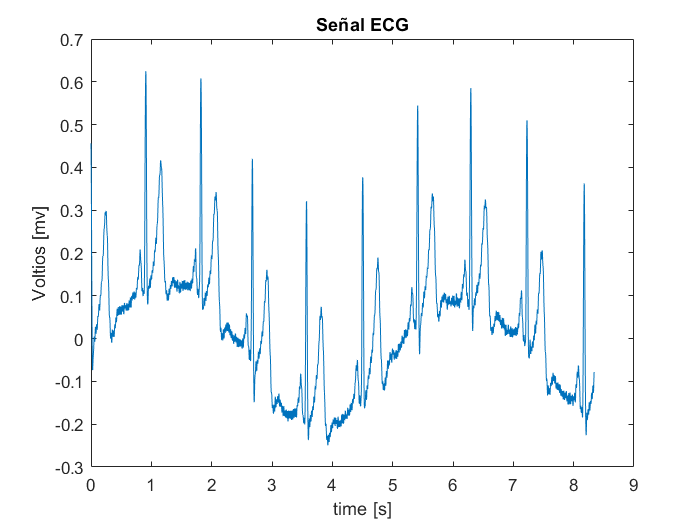

load('./ecg.mat') % cargar la matriz de la señal

%% inicialización de variables necesarias
Fs = 500;        %Frecuencia de muestreo
L = length(ecg); %Longitud de la señal
T = L/Fs;        %Duración de la señal


%vector entre 0 y 1/2 multiplicado por Fs
%vector entre 0 y Fs/2
f_med = Fs*(0:L/2)/L;
f_complete = (-L/2:L/2-1)*Fs/L;

%vector de tiempo de 10000 elementos
t = linspace(0, T, L);
w = f_med*2*pi;             %vector omega, de frecuencias angulares
%epsilon = 0.00000000001;

plot(t, ecg)
xlabel('time [s]')
ylabel('Voltios [mv]')
title('Señal ECG')

**Ahora analizaremos las componentes frecuenciales de la señal ECG**

*(note que la señal está aparentemente contaminada con un seno).*

Primero mostramos el espectro de la señal:

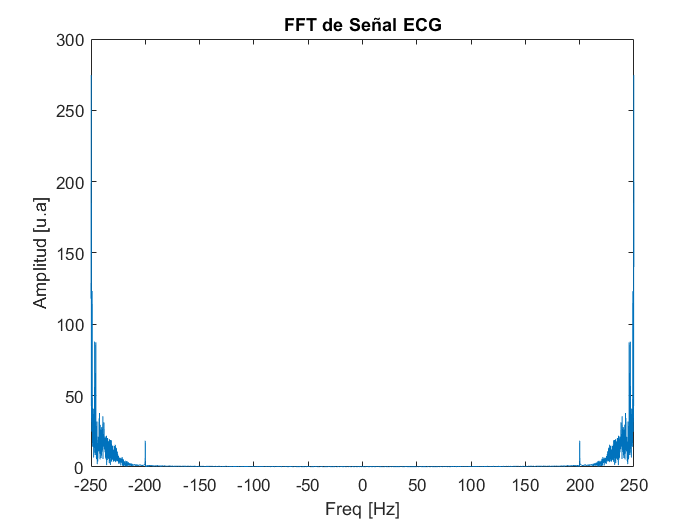


ecg_fft = fft(ecg)'; 

figure, plot(f_complete, abs( ecg_fft ));
xlabel('Freq [Hz]');
ylabel('Amplitud [u.a]');
title('FFT de Señal ECG');

Con base a ese espectro experimentamos un poco y borramos las componentes que creemos que le están dando ese comportamiento sinusoidal a la onda, note que el comportamiento sinusoidal es muy obvio por lo tanto su magnitud en frecuencia debería ser bastante alta.

### Método 0:

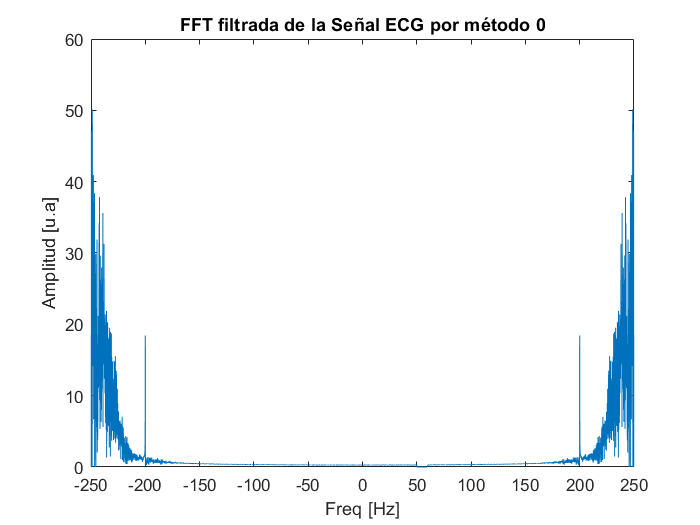


ecg_fft((f_complete >= 50) & (f_complete <= 60)) = 0; %borramos la banda en la que puede haber contaminación
                                    %por ruido de alimentación eléctrica
ecg_fft(abs(ecg_fft) >= 80) = 0;    %borramos los picos más altos

figure, plot(f_complete, abs( ecg_fft( 1: end) ));
xlabel('Freq [Hz]');
ylabel('Amplitud [u.a]');
title('FFT filtrada de la Señal ECG por método 0');

Y recontruimos la señal para ver los resultados: 

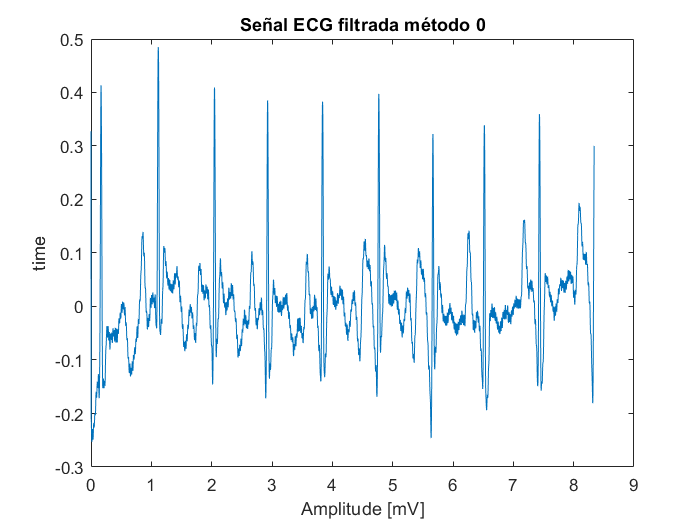

y_f = ifft(ecg_fft, 'Symmetric');

plot(t, y_f);
xlabel('Amplitude [mV]');
ylabel('time');
title('Señal ECG filtrada método 0');

### Ahora vamos a replicar estos resultados a partir de filtros hechos con polos y ceros: 

Necesitaremos un rechazabanda en  el rango correspondiente a las componentes en frec. de este seno *[248.9 Hz, 249.8 Hz, 245.6 Hz, 246.6 Hz]. *

Y también deberemos quitar el ruido que pueda venir de la de la frecuencia 5*0Hz  o  60Hz* debido a que ahí hay ruido de alimentación. 

***Primera aproximación:***

Se trató de hacer un pasa bajas que rechaze *[248.9 Hz, 249.8 Hz, 245.6 Hz, 246.6 Hz], *ya que todas estas están muy cerca.

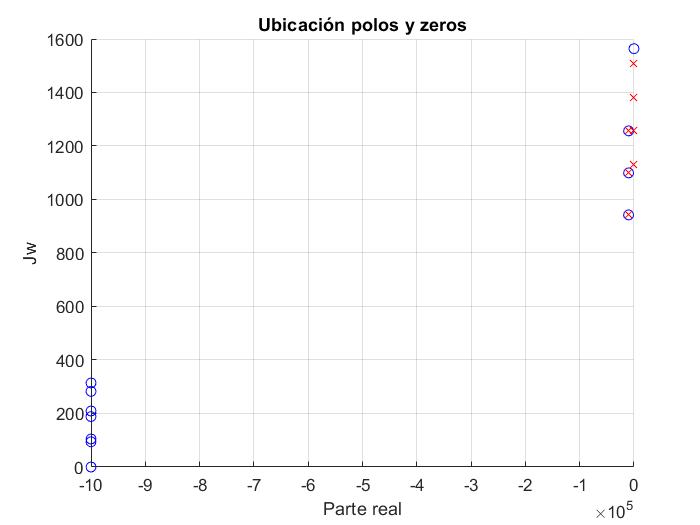

dist = 0.01;
zeros1 = [linspace(150, 200, 3)].*(2*pi*1i) - dist*1000000;
zeros2 = [linspace(0, 45, 4)].*(2*pi*1i) - dist*100000000;
zeros3 = [linspace(0, 50, 4)].*(2*pi*1i) - dist*100000000;
zeros4 = [248.9].*(2*pi*1i) - dist*0.000000001;
zeros = [zeros1 zeros2 zeros3 zeros4];

poles1 = [linspace(150, 200, 3)].*(2*pi*1i)- dist*1000000; 
poles2 = [linspace(220, 240, 2)].*(2*pi*1i)- dist*100000;
poles3 = [linspace(180, 240, 4)].*(2*pi*1i)- dist*90000;

poles = [poles1 poles2 poles3];



plot_poles_and_zeros(poles, zeros);

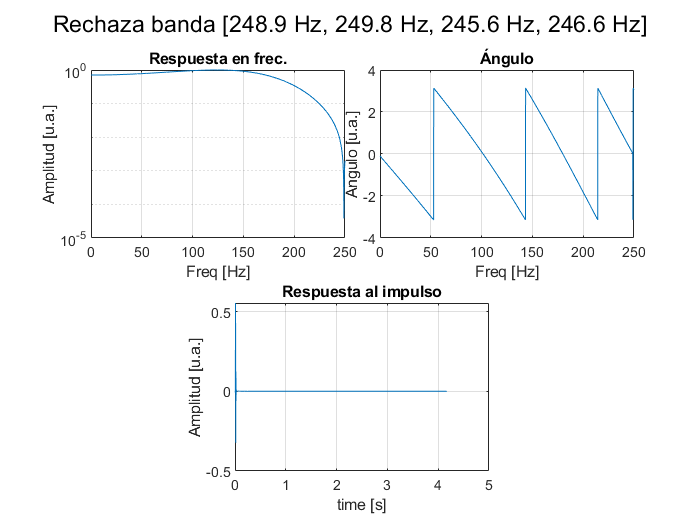

H_H = compute_rect_window(w, poles, zeros);

plot_all_about_win(f_med, t, H_H, 'Rechaza banda [248.9 Hz, 249.8 Hz, 245.6 Hz, 246.6 Hz]');

### Resultados:

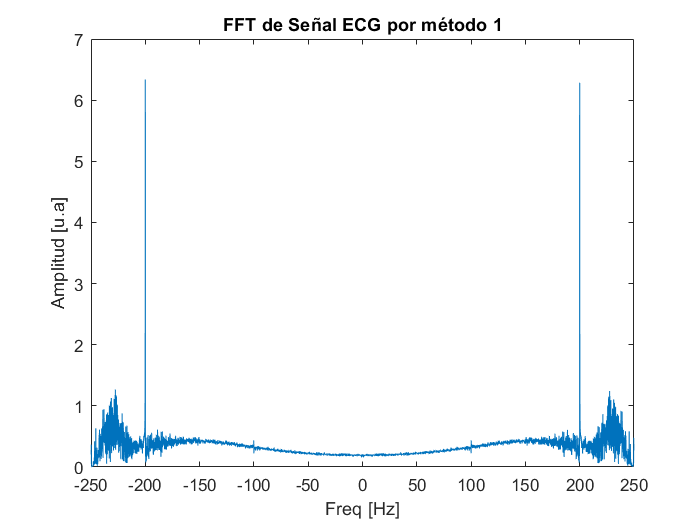

ecg_fft = fft(ecg)'; 

%Generar respuesta en frecuencia completa del filtro
H_H_C = [fliplr(H_H(1:end-1)) conj( H_H(2:end) ) ]; %flip left to right
ecg_fft1 = ecg_fft.*H_H_C;


figure, plot(f_complete, abs(ecg_fft1));
xlabel('Freq [Hz]');
ylabel('Amplitud [u.a]');
title('FFT de Señal ECG por método 1');

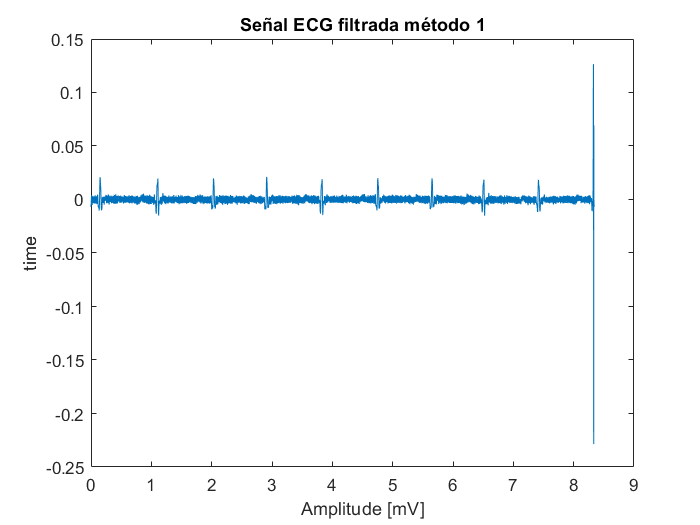


y_f = ifft(ecg_fft1, 'Symmetric');

figure, plot(t, y_f);
xlabel('Amplitude [mV]');
ylabel('time');
title('Señal ECG filtrada método 1');

Podemos ver que este filtro tiene éxito en quitar el comportamiento sinuoide pero fracasa debido a que es muy *'invasivo'.*

Ahora intentaremos a través del uso de ventanas notch para borrar esas frecuencias que vemos que son problemáticas.

### Método 2: 

Creación de los Notch para  *[248.9 Hz, 249.8 Hz, 245.6 Hz, 246.6 Hz]  y* 5*0Hz  o  60Hz.*

Para esta tarea creamos una función que construye un notch para una frecuencia a rechazar dada, esto lo logramos usando solo polos y el truco de sacar '*el complemento de la respuesta en frec. señal*', esto ya que inicialmente sólo con polos podíamos obtener una señal del estilo delta dirac, entonces al invertirla obtendríamos el notch.

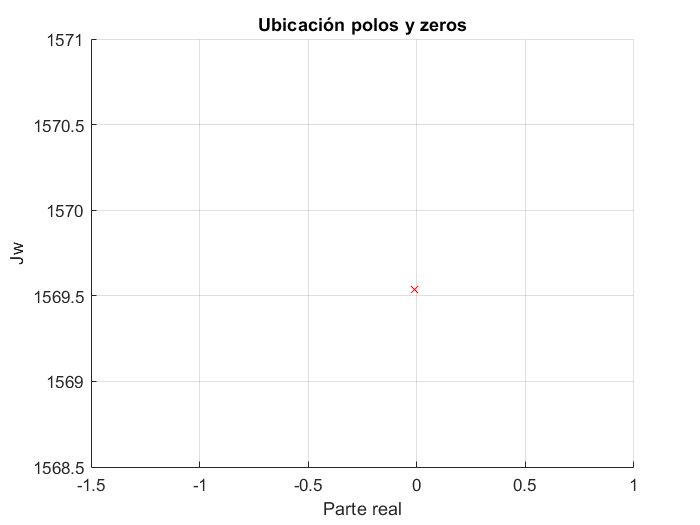

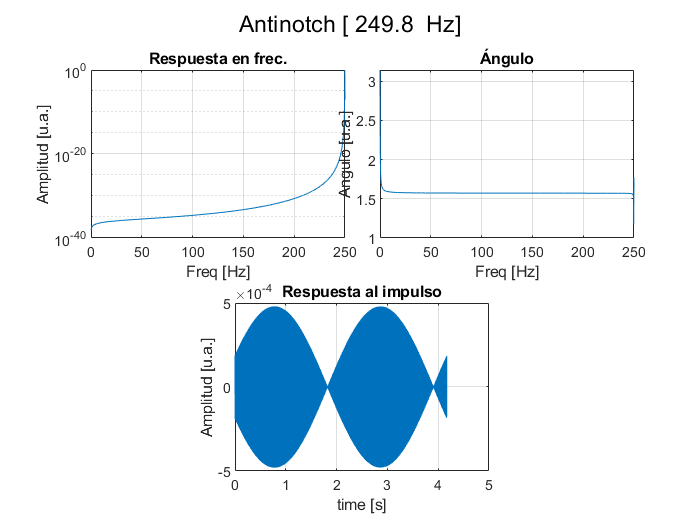

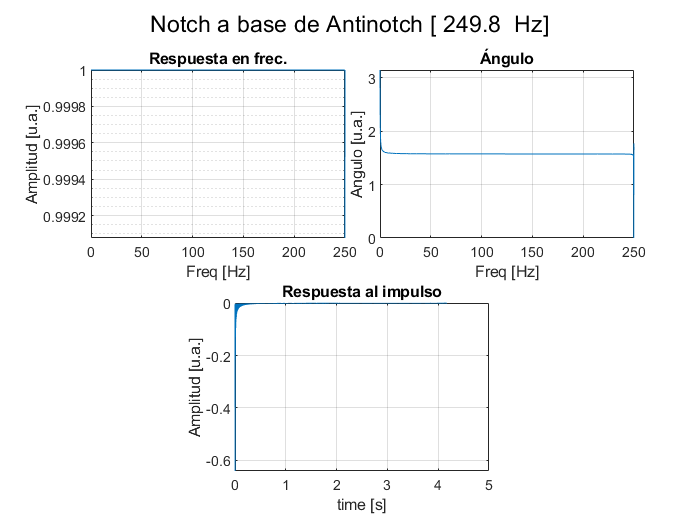

H_H1 = create_notch_win(0.01, t, f_med, w, 249.8, true);

H_H2 = create_notch_win(0.01, t, f_med, w, 248.9, false);
H_H3 = create_notch_win(0.01, t, f_med, w, 245.6, false);
H_H4 = create_notch_win(0.01, t, f_med, w, 246.6, false);

H_H5 = create_notch_win(0.01, t, f_med, w, 50, false);
H_H6 = create_notch_win(0.01, t, f_med, w, 60, false);


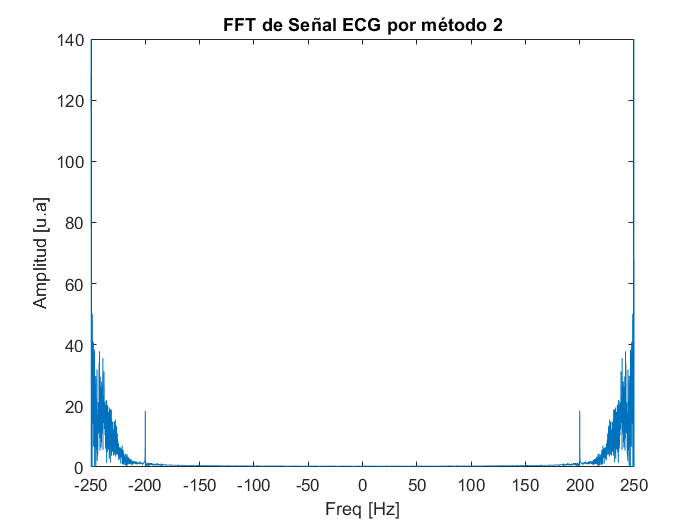

% agregamos un cero al final de la fft porque la forma en que se hace la 
% respuesta en frecuencia completa quita un valor de la transformada y en
% este caso ese valor era importante

ecg_fft = [fft(ecg)' 0]; 
f_complete = (-L/2:L/2)*Fs/L;

%filtrado
ecg_fft1 = ecg_fft.*H_H1.*H_H2.*H_H3.*H_H4.*H_H5;



figure, plot(f_complete, abs(ecg_fft1));
xlabel('Freq [Hz]');
ylabel('Amplitud [u.a]');
title('FFT de Señal ECG por método 2');

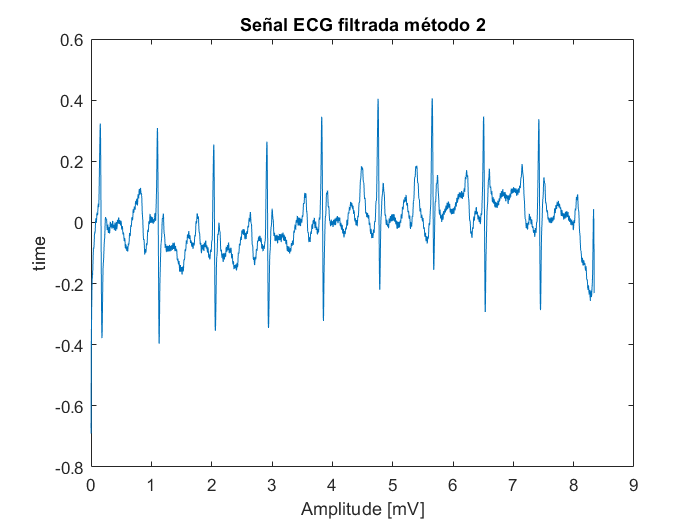

y_f = ifft(ecg_fft1, 'Symmetric');

plot(t, y_f(1:end-1));
xlabel('Amplitude [mV]');
ylabel('time');
title('Señal ECG filtrada método 2');